
threshold = 0.98;
smoothing = [1 1];
margin = 1;
minPatchSize = 100;

matSize = size(experiment1,3);
Avec = zeros(matSize);
Pvec = zeros(matSize);
Bvec = zeros(matSize);


for i=1:matSize
    [AvecC,PvecC,BvecC,BlobCell,LogMat] = GetAP_MainPatch3(experiment1(:,:,i),threshold,smoothing,margin,minPatchSize);
    Avec(i) = AvecC(1);
    Pvec(i) = PvecC(1);
    Bvec(i) = BvecC(1);
end

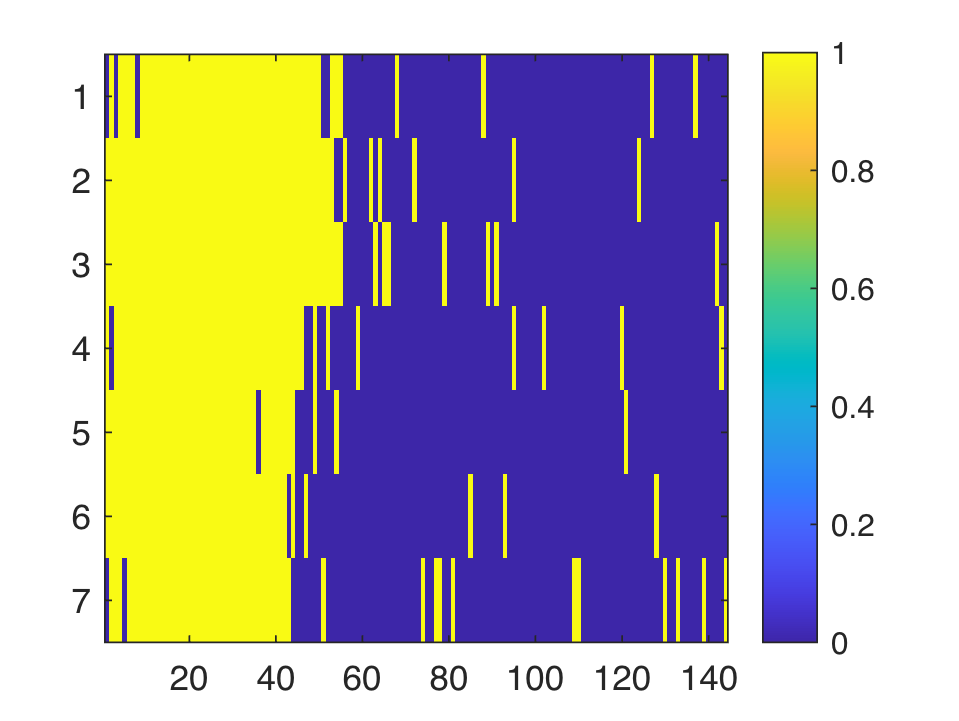



t =706;
[AvecC,PvecC,BvecC,BlobCell,LogMat] = GetAP_MainPatch3(experiment1(:,:,t),threshold,smoothing,margin,minPatchSize);

current = LogMat(:,:);
imagesc(current);
caxis([0 1]);
colorbar;

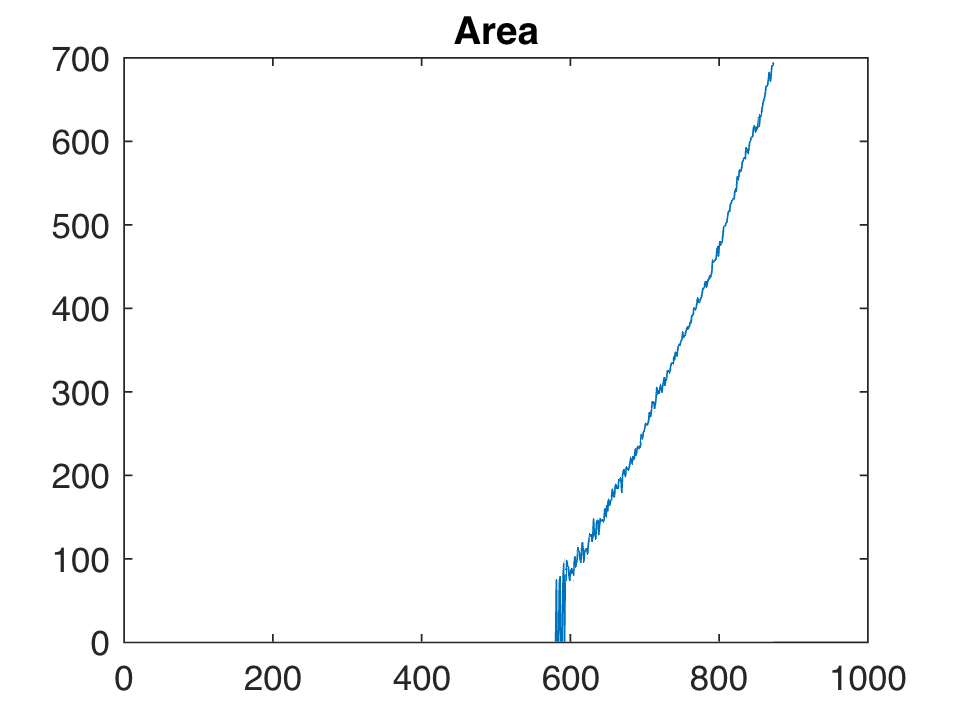



plot(Avec);
title("Area");

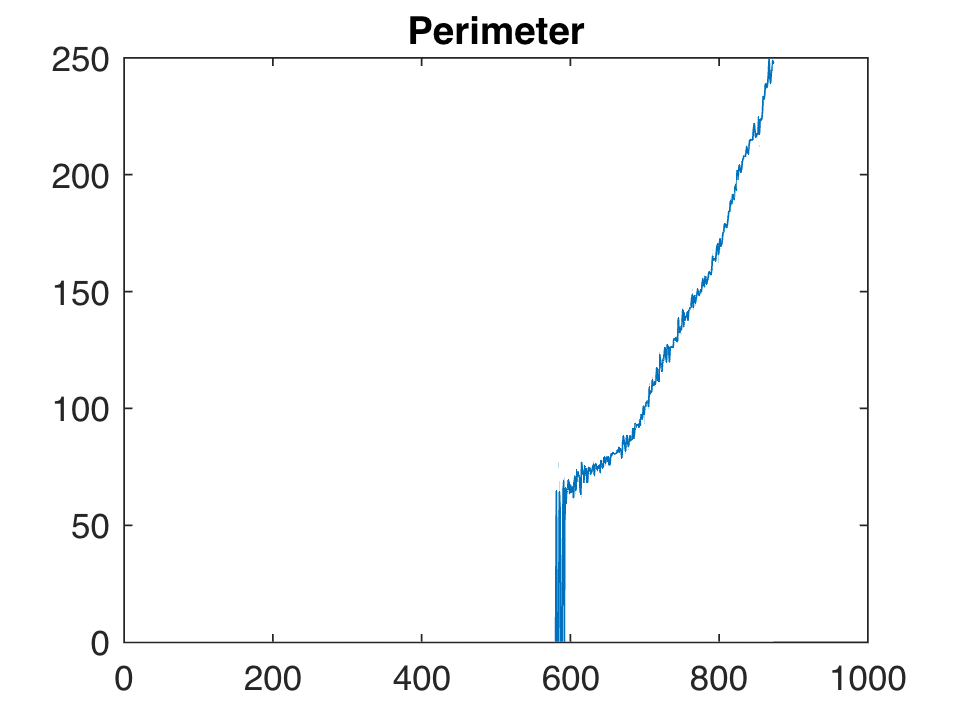

plot(Pvec);
title("Perimeter");

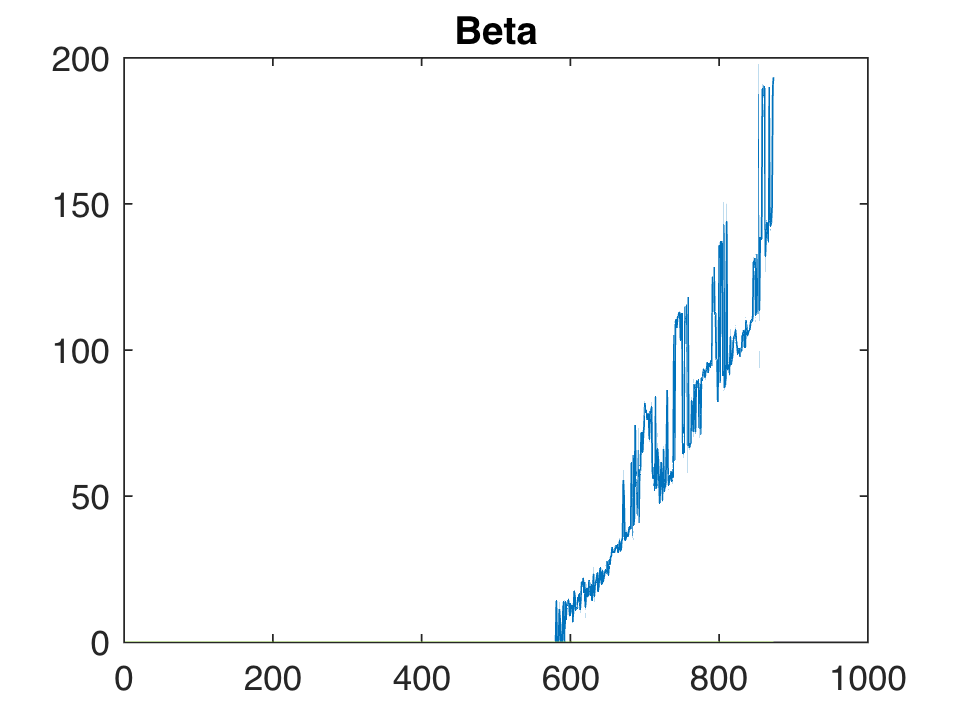

plot(Bvec);
title("Beta");